# Demo 05: noise test 

A demo script to check the noise statistics. Not all spectral seperation modes and processing steps gives a proper SNR metric. This script is to verify the standard normal distribution of data, image and metabolite amplitudes after every processing step. Download noise data (800 MB "phantom-DMI-noise.tar.gz") from [zenodo.org (DOI: 10.5281/zenodo.14652737)](https://doi.org/10.5281/zenodo.14652737) to follow this excercise. The way we estimate the coil maps from average echo/phase-cyled volumes leads to additional variance inflation of the water SNR maps. If the water inflation is less than the maximum singular value during coil combination step during the actual measurement, this inflation can be safely ignored. The inflation factor can be validated by Marchenko-Pasteur distribution or providing non-averaged input volume for the coil map estimation.

## FISP CSI dataset with acquistion weighting

% add all dependencies
addpath(genpath('/ptmp/pvalsala/Packages/mapVBVD'))
addpath(genpath('/ptmp/pvalsala/Packages/DeuteMetCon'))
addpath(genpath('/ptmp/pvalsala/Packages/OXSA'))

%data path
sn='/ptmp/pvalsala/deuterium/dataForPublication/phantom-DMI-Noise';

fn=fullfile(sn,'meas_MID00750_FID11717_rpcsi_fid_Stan_res15_6_TR36_5min_0FA.dat');
metabolites=getMetaboliteStruct('phantom',0);
CSI_setting={'metabolites',metabolites,'parfor',true,...
    'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0]*0,'mask',[],'Solver','IDEAL'};
mcobj_fisp=MetCon_CSI(fn,CSI_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   324.1 MB read in    6 s
starting reco
initial CSI data size:           10   25   25   25  256
final CSI data size:           10   25   25   25  256
reco  time =    3.9 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Metabolite mapping time =    6.0 s


### Plot FISP noise characteristics

verify noise is uniformly distributed

 figure,
set(gcf,'Position',[0,0,1400,800])
tiledlayout(2,5,'TileSpacing','compact','Padding','compact')

%raw data
sig=permute(mcobj_fisp.twix.image{''},[2 1 3:8]);
sig=mcobj_fisp.D*sig(:,:); % noise decorrelation
sig=sig(:,abs(sum(sig,1))>0);%take all samples without zeropadding

nexttile(1),histogram(real(sig(:))),title(sprintf('data|real\nμ±σ=%.2f±%.2f',mean(real(sig(:))),std(real(sig(:)))));
nexttile(1+5),qqplot(real(sig(:))),title('data|real| QQ');
nexttile(2),histogram(imag(sig(:))),title(sprintf('data|imag\nμ±σ=%.2f±%.2f',mean(imag(sig(:))),std(imag(sig(:)))));
nexttile(2+5),qqplot(imag(sig(:))),title('data|imag| QQ');

% reconstructed images
nexttile(3),histogram(real(mcobj_fisp.img(:))),title(sprintf('Image|real\nμ±σ=%.1f±%.2f',mean(real(mcobj_fisp.img(:))),std(real(mcobj_fisp.img(:)))));
nexttile(3+5),qqplot(real(mcobj_fisp.img(:))),title('image|real|QQ');
nexttile(4),histogram(imag(mcobj_fisp.img(:))),title(sprintf('Image | imag\nμ±σ=%.1f±%.2f',mean(real(mcobj_fisp.img(:))),std(real(mcobj_fisp.img(:)))));
nexttile(4+5),qqplot(imag(mcobj_fisp.img(:))),title('image|imag|QQ')

%Metabolite maps
[~,scl_fac]=mcobj_fisp.getNormalized();
% scl_fac is the eucledian norm of complex weights used during spectral
% seperation is used for normalization to SNR units.
Metcon_SNR=real(reshape(mcobj_fisp.Metcon,[],4)./scl_fac')/sqrt(2);
% the coil maps are calculated from average of all echo image: which lead
% to inflated water SNR in noise only case as predicted by Marchenko–Pastur distribution : (1+sqrt(256/25^3)).^2/(1-sqrt(256/25^3)).^2
Metcon_SNR=Metcon_SNR(:,2:end); %exclude water
nexttile(5),histogram(Metcon_SNR(:)),title(sprintf('MetCon| real\nμ±σ=%.2f±%.2f',mean(Metcon_SNR(:)),std(Metcon_SNR(:))));
nexttile(5+5),qqplot(Metcon_SNR(:)),title('MetCon|real| QQ');
uicontrol('Visible','off')

## CSI-bSSFP dataset with acquistion weighting

%data path
sn='/ptmp/pvalsala/deuterium/dataForPublication/phantom-DMI-Noise';

fn=fullfile(sn,'meas_MID00749_FID11716_rpcsi_ssfp_Stan25_15_6mm_5mins_0FA.dat');
metabolites=getMetaboliteStruct('phantom',0);
CSI_setting={'metabolites',metabolites,'parfor',true,...
    'doCoilCombine','adapt1','doZeropad',[0.5 0.5 0.5 0]*0,'mask',[],'Solver','IDEAL-modes'};
mcobj_ssfp=MetCon_CSI(fn,CSI_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   163.8 MB read in    6 s
starting reco
initial CSI data size:           10  25  25  25  64   4
final CSI data size:           10  25  25  25  64   4
reco  time =    2.9 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Metabolite mapping time =    4.8 s


### Plot CSI-bSSFP noise characteristics

verify noise is uniformly distributed and has unit standard deviation after every processing step.

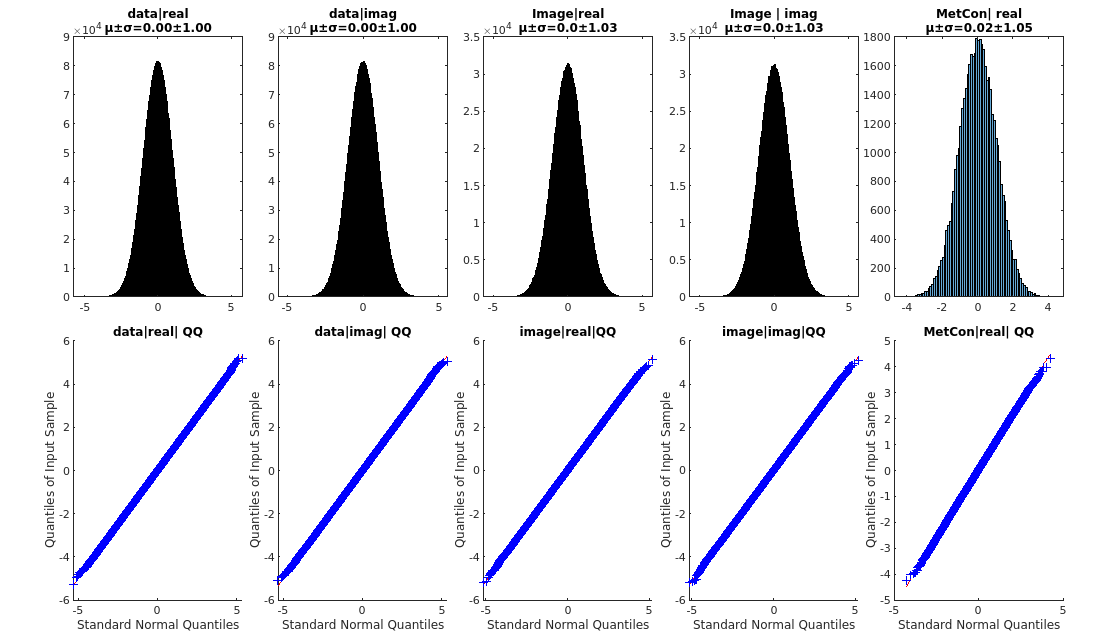

 figure,
set(gcf,'Position',[0,0,1400,800])
tiledlayout(2,5,'TileSpacing','compact','Padding','compact')

%raw data
sig=permute(mcobj_ssfp.twix.image{''},[2 1 3:8]);
sig=mcobj_ssfp.D*sig(:,:); % noise decorrelation
sig=sig(:,abs(sum(sig,1))>0);%take all samples without zeropadding

nexttile(1),histogram(real(sig(:))),title(sprintf('data|real\nμ±σ=%.2f±%.2f',mean(real(sig(:))),std(real(sig(:)))));
nexttile(1+5),qqplot(real(sig(:))),title('data|real| QQ');
nexttile(2),histogram(imag(sig(:))),title(sprintf('data|imag\nμ±σ=%.2f±%.2f',mean(imag(sig(:))),std(imag(sig(:)))));
nexttile(2+5),qqplot(imag(sig(:))),title('data|imag| QQ');

% reconstructed images
nexttile(3),histogram(real(mcobj_ssfp.img(:))),title(sprintf('Image|real\nμ±σ=%.1f±%.2f',mean(real(mcobj_ssfp.img(:))),std(real(mcobj_ssfp.img(:)))));
nexttile(3+5),qqplot(real(mcobj_ssfp.img(:))),title('image|real|QQ');
nexttile(4),histogram(imag(mcobj_ssfp.img(:))),title(sprintf('Image | imag\nμ±σ=%.1f±%.2f',mean(real(mcobj_ssfp.img(:))),std(real(mcobj_ssfp.img(:)))));
nexttile(4+5),qqplot(imag(mcobj_ssfp.img(:))),title('image|imag|QQ')

%Metabolite maps
[~,scl_fac]=mcobj_ssfp.getNormalized();
% scl_fac is the eucledian norm of complex weights used during spectral
% seperation is used for normalization to SNR units.
Metcon_SNR=real(reshape(mcobj_ssfp.Metcon,[],4))./(scl_fac)'/sqrt(2);
% the coil maps are calculated from average of all echo image: which lead
% to inflated water SNR in noise only case as predicted by Marchenko–Pastur distribution : (1+sqrt(64*4/25^3)).^2/(1-sqrt(64*4/25^3)).^2
Metcon_SNR=Metcon_SNR(:,2:end); % exclude water
nexttile(5),histogram(Metcon_SNR(:)),title(sprintf('MetCon| real\nμ±σ=%.2f±%.2f',mean(Metcon_SNR(:)),std(Metcon_SNR(:))));
nexttile(5+5),qqplot(Metcon_SNR(:)),title('MetCon|real| QQ');

## multiecho-bSSFP dataset with acquistion weighting

 The zeros added by the translation to compensate chemical shifts along read were removed by recomputing the metabolite amplitudes

%data path
sn='/ptmp/pvalsala/deuterium/dataForPublication/phantom-DMI-Noise';
% trufi sequence acquire noise data only when parallel imaging is enabled. Therefore, we acquire noise scan with 0 flip angle seperately.
twix_noise=mapVBVD(fullfile(sn,'meas_MID00735_FID11702_pvrh_trufi_5E_noise_12P5mm.dat'),'rmos');

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
    40.4 MB read in    7 s


[D_noise,D_image,noise_info]=CalcNoiseDecorrMat(twix_noise);
%D_image is the noise correlation from image data measured with 0 FA

### `assemble inputs and processing flags`

ME_setting={'NoiseDecorr',D_image,'mask',[],'metabolites',metabolites,...
            'doPhaseCorr',false,'doZeropad',[1 1 1]*0.5,'parfor',true,'fm','IDEAL','Solver','IDEAL-modes'};
fn=fullfile(sn,'meas_MID00752_FID11719_pvrh_trufi_5E_18PC_12P5mm_FA50_s4_r180_0FA.dat');
metabolites=getMetaboliteStruct('phantom',0);
mcobj_me=MetCon_ME(fn,ME_setting{:});

Software version: VD (!?)
Reader version: 1660732089 (UTC: 17-Aug-2022 10:28:09)
Scan 1/1, read all mdhs:
   428.6 MB read in    7 s


starting reco
reco  time =   12.6 s
estimating field map(1/2) 
estimating metabolities(2/2) 
Performed pixel shift along read: (0.0,-2.2,-5.2 ,-7.2) mm
Metabolite mapping time =   18.8 s


mcobj_me.performMetCon();% redo to remove pixel shift

estimating field map(1/2) 
estimating metabolities(2/2) 


### Plot ME-bSSFP noise characteristics

verify whether noise is uniformly distributed. 

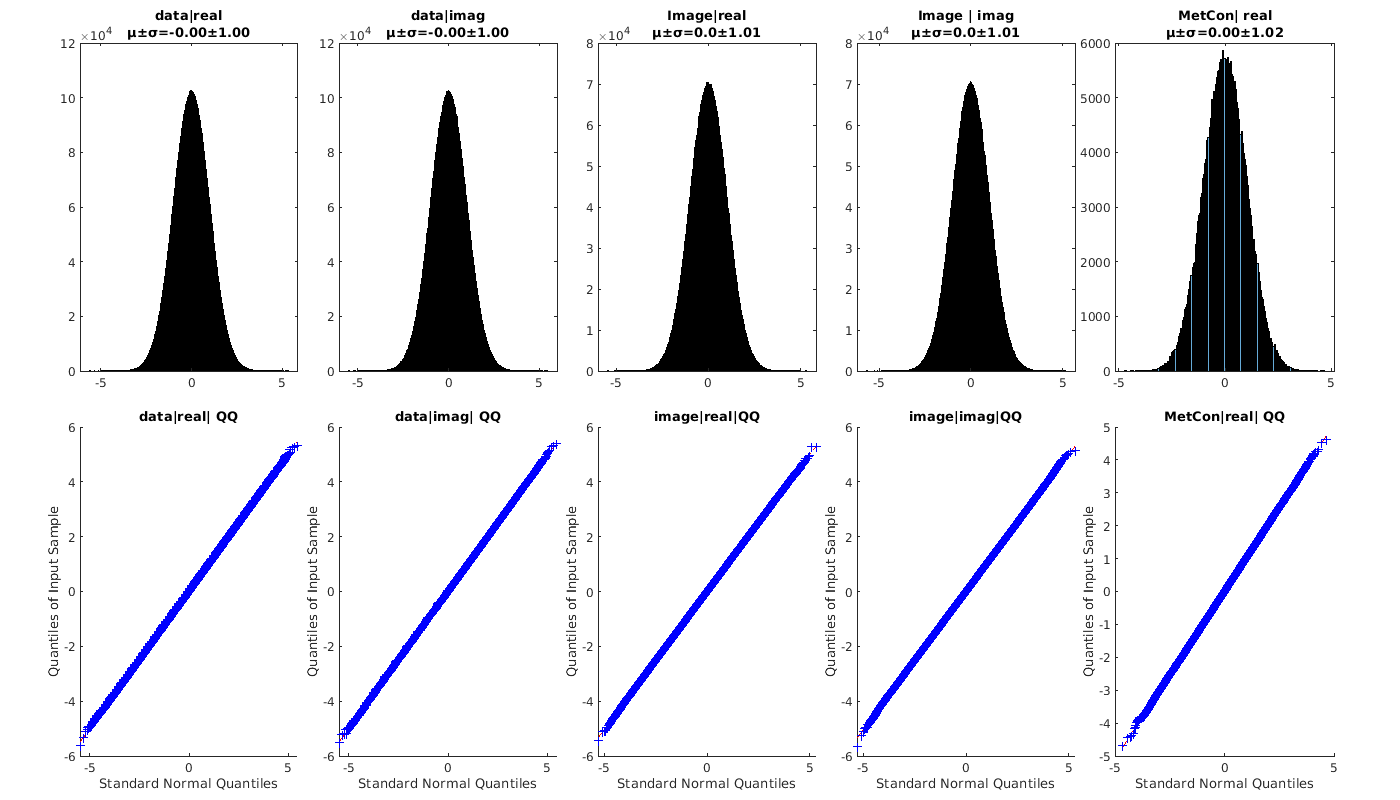

set(gcf,'Position',[0,0,1400,800])
% set(gcf,'Position',[0,0,1400,800])
tiledlayout(2,5,'TileSpacing','compact','Padding','compact')

%raw data
sig=permute(mcobj_me.twix.image{''},[2 1 3:8]);
sig=mcobj_me.D*sig(:,:); % noise decorrelation
sig=sig(:,abs(sum(sig,1))>0);%take all samples without zeropadding

nexttile(1),histogram(real(sig(:))),title(sprintf('data|real\nμ±σ=%.2f±%.2f',mean(real(sig(:))),std(real(sig(:)))));
nexttile(1+5),qqplot(real(sig(:))),title('data|real| QQ');
nexttile(2),histogram(imag(sig(:))),title(sprintf('data|imag\nμ±σ=%.2f±%.2f',mean(imag(sig(:))),std(imag(sig(:)))));
nexttile(2+5),qqplot(imag(sig(:))),title('data|imag| QQ');

% reconstructed images
nexttile(3),histogram(real(mcobj_me.img(:))),title(sprintf('Image|real\nμ±σ=%.1f±%.2f',mean(real(mcobj_me.img(:))),std(real(mcobj_me.img(:)))));
nexttile(3+5),qqplot(real(mcobj_me.img(:))),title('image|real|QQ');
nexttile(4),histogram(imag(mcobj_me.img(:))),title(sprintf('Image | imag\nμ±σ=%.1f±%.2f',mean(imag(mcobj_me.img(:))),std(imag(mcobj_me.img(:)))));
nexttile(4+5),qqplot(imag(mcobj_me.img(:))),title('image|imag|QQ')

%Metabolite maps
[~,scl_fac]=mcobj_me.getNormalized();
% scl_fac is the eucledian norm of complex weights used during spectral
% seperation is used for normalization to SNR units.
Metcon_SNR=real(reshape(mcobj_me.Metcon,[],4)./scl_fac')/sqrt(2);
Metcon_SNR=Metcon_SNR(:,2:end); %exclude water
nexttile(5),histogram(Metcon_SNR(:)),title(sprintf('MetCon| real\nμ±σ=%.2f±%.2f',mean(Metcon_SNR(:)),std(Metcon_SNR(:))));
nexttile(5+5),qqplot(Metcon_SNR(:)),title('MetCon|real| QQ');
uicontrol('Visible','off')

PDF export 17 inch x 28 inch 600 dpi